# 2.3Parallel implementation of GMRES.

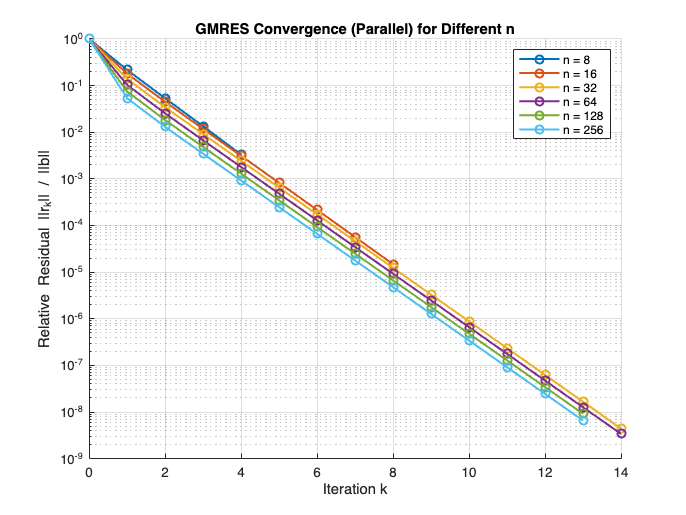

clear; clc; close all;
%%Arnoldi iteration in parallel using parfor
function [Q, H] = arnoldi_parallel(A, b, m)
% input:
%       A: The square matrix to be processed
%       b: Initial vector (I used a random number between 0 and 1 to test)
%       m: Number of iterations (that is, how many Krylov subspace vectors
%       to construct)
%
% output:
%       Q: Matrix containing an orthogonal basis (size n*(m+1))
%       H: Upper Hessenberg matrx (size (m+1)*m)  
%
    n = length(b);
    Q = zeros(n, m+1);
    H = zeros(m+1, m);
    Q(:,1) = b / norm(b);% The initial vector u is normalized and stored as the first column of Q (q1)(this is the first step of constructing Krylov subspace),also 
    
    for k = 1:m
        v = A * Q(:,k);  % get a new vector
        % Parallel Gram-Schmidt (dot products in parallel)
        alpha = zeros(k,1);
        parfor j = 1:k
            alpha(j) = Q(:,j)' * v  % inner product,calculate the projection
        end
        for j = 1:k
            v = v - alpha(j) * Q(:,j);   % Subtract the projections 
            H(j,k) = alpha(j);     
        end
        H(k+1,k) = norm(v);   % Calculate the new element of the Hessenberg matrix

        % Normalize the new orthogonal basis
        if H(k+1, k) > 1e-14
            Q(:,k+1) = v / H(k+1, k);
        else
            break; % break the iteration
        end
    end
end

%% GMRES Algorithm in Parallel 
function [x, R, final_iter] = gmres_parallel(A, b, m, tol)
% input:
%       A:The coefficient matrix in the equation Ax=b.It's size is n by n
%       b: The right-hand side vector of the linear system of Ax=b
%       m: Number of iterations (that is, how many Krylov subspace vectors
%       to construct)
%       tol: The tolerance for stopping criterion 
%
% output:
%       x: The approximate solution to the linear system Ax=b obtained through the GMRES algorithm.
%       R: Residuals 
%       final_iter: The actual iteration count used (may be < m if converged early)
%
    n = length(b);
    x_0 = zeros(n,1);      %Initialize the first solution x is a zeros vector
    r_0 = b - A*x_0;         %The first residual is r_0
    beta = norm(r_0);

    % history of residual norms
    R = zeros(m+1,1);
    R(1) = beta / norm(b);

    [Q, H] = arnoldi_parallel(A, r_0, m); % Call the Arnoldi iteration function to get orthonogal basis Q and upper Hessenberg matrix H

    final_iter = m;  % default: use all m steps if not converged earlier

    % GMRES main loop: each iteration solves a small least squares problem
    for k = 1:m
        % Sub-block of H: size (k+1)-by-k
        Hk = H(1:k+1, 1:k);
       
        e1 = zeros(k+1,1);  % Construct e1=(1,0,0,...,0)^(*) 
        e1(1) = beta;       %let the first element of e1 is the norm of r_0  
        yk = Hk \ e1;        % Least squares problem: min || H * y - beta * e1 ||
        xk = x_0 + Q(:,1:k)*yk;  % The solution estimate x at step k
        rk = b - A*xk;         %  Compute new residual
        R(k+1) = norm(rk) / norm(b);

        % Check stopping criterion
        if R(k+1) < tol
            final_iter = k;
            break;
        end
    end

    % Build final solution x using final_iter
    H_used = H(1:final_iter+1, 1:final_iter);
    Q_used = Q(:,1:final_iter);
    e1_used = zeros(final_iter+1,1);
    e1_used(1) = beta;
    y_final = H_used \ e1_used;
    x = x_0 + Q_used * y_final;

    % Truncate the residual history to 0...final_iter
    R = R(1:final_iter+1);
end


%% Application: Parallel GMRES for Different n 
clear; clc; close all;    % Clear workspace and close figures

n_values = [8, 16, 32, 64, 128, 256];
tol = 1e-8;  % stopping threshold
time_record_parallel = zeros(size(n_values)); %use for recording the runing time
colors = lines(length(n_values));

% Plot for residual curves
figure;
hold on;
title('GMRES Convergence (Parallel) for Different n');
xlabel('Iteration k');
ylabel('Relative Residual ||r_k|| / ||b||');
set(gca, 'YScale', 'log');

fid = fopen('GMRES_results_parallel.txt','w');     % Write the approximate result x and residual histories for different n in one file
if fid==-1                                % To check if opening the file successfully
    error('Cannot open filr for writing results');
end
grid on;

for i = 1:length(n_values)
    n = n_values(i);
    m = floor(n/2);  % maximum subspace dimension

    % Construct tridiagonal matrix A (sparse) with -4 on main diagonal, 1 on sub-/super-diagonal
    e = ones(n,1);
    A = spdiags([e -4*e e], -1:1, n, n);
    % Construct right-hand side vector b = [1/n, 2/n, ..., n/n]^*
    b = (1:n)'/n;

    tic; %timing stars
    [x, residuals, final_iter] = gmres_parallel(A, b, m, tol);
    elapsed_time = toc;
    time_record_parallel(i) = elapsed_time;
    % Plot residual history
    plot(0:final_iter, residuals, '-o', 'LineWidth',1.5, ...
         'Color', colors(i,:), 'DisplayName', sprintf('n = %d', n));
    % Write the results into the file
    fprintf(fid, '----------------------------------------------\n');
    fprintf(fid, 'n = %d, m = %d\n', n, m);
    fprintf(fid, 'CPU Time (seconds)= %.6f\n', elapsed_time);
    fprintf(fid, 'Estimated solution x:\n');
    fprintf(fid, '%f\n', x);
    fprintf(fid, 'Residual record (||r_k|| / ||b||):\n');
    fprintf(fid, '%f\n', residuals);
    fprintf(fid, '\n');   
end

legend show;
hold off;

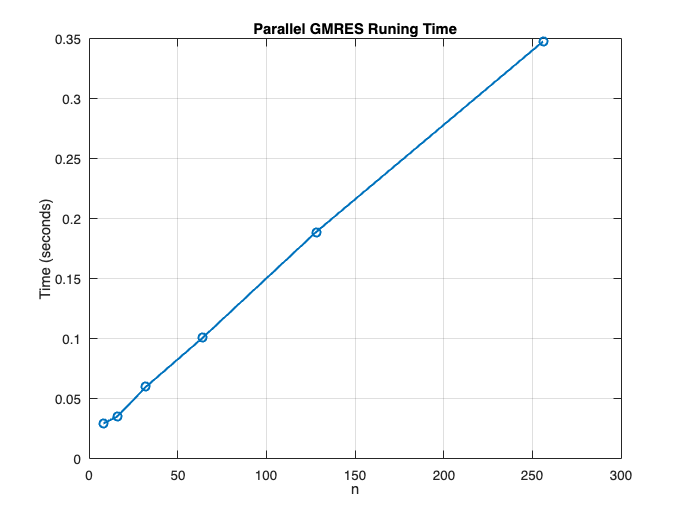


% Plot CPU time 
figure;
plot(n_values, time_record_parallel, '-o', 'LineWidth',1.5);
title('Parallel GMRES Runing Time');
xlabel('n');
ylabel('Time (seconds)');
grid on;